# **Book example 2.9 Two Tank System**

## **Nonlinear System Establishing**

syms At ka C0 Dv kh kt
syms x1 x2 x3 x4 u1 u2 v1 v2 v3
syms x10 x20 x30  x40 u10 u20 v10 v20 v30

f1 = 1/At*(ka*(u1+u2)-C0*sqrt(x1-x2));
f2 = 1/At*((C0*sqrt(x1-x2)-Dv*sqrt(x2)*v1));
f3 = 1/(At*x1)*((v2-x3)*ka*u1+(v3-x3)*ka*u2);
f4 = 1/(At*x2)*((x3-x4)*C0*sqrt(x1-x2));
f = [f1;f2;f3;f4]

$$f = \left(\begin{array}{c} \frac{\mathrm{ka}\,\left(u_{1}+u_{2}\right)-C_{0}\,\sqrt{x_{1}-x_{2}}}{\mathrm{At}}\\ \frac{C_{0}\,\sqrt{x_{1}-x_{2}}-\mathrm{Dv}\,v_{1}\,\sqrt{x_{2}}}{\mathrm{At}}\\ \frac{\mathrm{ka}\,u_{1}\,\left(v_{2}-x_{3}\right)+\mathrm{ka}\,u_{2}\,\left(v_{3}-x_{3}\right)}{\mathrm{At}\,x_{1}}\\ \frac{C_{0}\,\sqrt{x_{1}-x_{2}}\,\left(x_{3}-x_{4}\right)}{\mathrm{At}\,x_{2}} \end{array}\right)$$

g1 = kh*x2;
g2 = kt*x4;
g = [g1;g2]

$$g = \left(\begin{array}{c} \mathrm{kh}\,x_{2}\\ \mathrm{kt}\,x_{4} \end{array}\right)$$

x = [x1;x2;x3;x4];% H1 H2 T1 T2
u = [u1;u2];% uw uc
v = [v1;v2;v3];% Av Tw Tc

## **Analytically Stationary Point and Linearlized System Calculation**

% Stationary point caculation by equation
[sol1,sol2,sol3,sol4] = solve([f1==0,f2==0,f3==0,f4==0],[x1,x2,x3,x4]);
disp(subs(simplify(sol1),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

$$\frac{{\mathrm{ka}}^{2}\,{\left(u_{10}+u_{20}\right)}^{2}\,\left({C_{0}}^{2}+{\mathrm{Dv}}^{2}\,{v_{10}}^{2}\right)}{{C_{0}}^{2}\,{\mathrm{Dv}}^{2}\,{v_{10}}^{2}}$$

disp(subs(simplify(sol2),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

$$\frac{{\mathrm{ka}}^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{\mathrm{Dv}}^{2}\,{v_{10}}^{2}}$$

disp(subs(simplify(sol3),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

$$\frac{u_{10}\,v_{20}+u_{20}\,v_{30}}{u_{10}+u_{20}}$$

disp(subs(simplify(sol4),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

$$\frac{u_{10}\,v_{20}+u_{20}\,v_{30}}{u_{10}+u_{20}}$$

**Analytically Linearlize the system with Jocabian matri1x**

A = subs(jacobian(f,x),[x1 x2 x3 x4 u1,u2,v1,v2,v3],[x10 x20 x30 x40 u10,u20,v10,v20,v30])

$$A = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1} & \sigma_{1} & 0 & 0\\ \sigma_{1} & -\frac{\frac{C_{0}}{2\,\sqrt{x_{10}-x_{20}}}+\frac{\mathrm{Dv}\,v_{10}}{2\,\sqrt{x_{20}}}}{\mathrm{At}} & 0 & 0\\ -\frac{\mathrm{ka}\,u_{10}\,\left(v_{20}-x_{30}\right)+\mathrm{ka}\,u_{20}\,\left(v_{30}-x_{30}\right)}{\mathrm{At}\,{x_{10}}^{2}} & 0 & -\frac{\mathrm{ka}\,u_{10}+\mathrm{ka}\,u_{20}}{\mathrm{At}\,x_{10}} & 0\\ \sigma_{2} & -\sigma_{2}-\frac{C_{0}\,\sqrt{x_{10}-x_{20}}\,\left(x_{30}-x_{40}\right)}{\mathrm{At}\,{x_{20}}^{2}} & \sigma_{3} & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{C_{0}}{2\,\mathrm{At}\,\sqrt{x_{10}-x_{20}}}\\ \sigma_{2}=\frac{C_{0}\,\left(x_{30}-x_{40}\right)}{2\,\mathrm{At}\,x_{20}\,\sqrt{x_{10}-x_{20}}}\\ \sigma_{3}=\frac{C_{0}\,\sqrt{x_{10}-x_{20}}}{\mathrm{At}\,x_{20}} \end{array}$$

B = subs(jacobian(f,u),[x1 x2 x3 x4 u1,u2,v1,v2,v3],[x10 x20 x30 x40 u10,u20,v10,v20,v30])

$$B = \left(\begin{array}{cc} \frac{\mathrm{ka}}{\mathrm{At}} & \frac{\mathrm{ka}}{\mathrm{At}}\\ 0 & 0\\ \frac{\mathrm{ka}\,\left(v_{20}-x_{30}\right)}{\mathrm{At}\,x_{10}} & \frac{\mathrm{ka}\,\left(v_{30}-x_{30}\right)}{\mathrm{At}\,x_{10}}\\ 0 & 0 \end{array}\right)$$

Bv = subs(jacobian(f,v),[x1 x2 x3 x4 u1,u2,v1,v2,v3],[x10 x20 x30 x40 u10,u20,v10,v20,v30])

$$Bv = \left(\begin{array}{ccc} 0 & 0 & 0\\ -\frac{\mathrm{Dv}\,\sqrt{x_{20}}}{\mathrm{At}} & 0 & 0\\ 0 & \frac{\mathrm{ka}\,u_{10}}{\mathrm{At}\,x_{10}} & \frac{\mathrm{ka}\,u_{20}}{\mathrm{At}\,x_{10}}\\ 0 & 0 & 0 \end{array}\right)$$

C = subs(jacobian(g,x),[x1 x2 x3 x4 u1,u2,v1,v2,v3],[x10 x20 x30 x40 u10,u20,v10,v20,v30])

$$C = \left(\begin{array}{cccc} 0 & \mathrm{kh} & 0 & 0\\ 0 & 0 & 0 & \mathrm{kt} \end{array}\right)$$

D = subs(jacobian(g,u),[x1 x2 x3 x4 u1,u2,v1,v2,v3],[x10 x20 x30 x40 u10,u20,v10,v20,v30])

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

Put in real numbers

% Given the input and disturbence and find stationary point
% // But I strongly doubt that when we do the exam, the given condition and
% // the requirement will not be like this

At = 0.785; % [m^2]
Dv = 2.66; % [m^(1/2)/s]
C0 = 0.056; % [[m^(5/2)/s]]
ka = 0.004; % [m^3/(V*s)]
kh = 2; % [V/m]
kt = 0.1; % [V/C]

% given input and disturbence conditions
uw0 = 5; % hot water valve [V]
uc0 = 5; % cold water valve [V]
Av0 = 0.0122; % area of outlet valve [m^2]
Tw0 = 60; % temperature of the hot water [C]
Tc0 = 30; % temperature of the cold water [C]

u10 = uw0;
u20 = uc0;
v10 = Av0;
v20 = Tw0;
v30 = Tc0;

% Calculate the stationary point
x10 = eval(subs(simplify(sol1),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

x10 =        2.0295


x20 = eval(subs(simplify(sol2),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

x20 =        1.5193


x30 = eval(subs(simplify(sol3),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

x30 =     45


x40 = eval(subs(simplify(sol4),[u1,u2,v1,v2,v3],[u10,u20,v10,v20,v30]))

x40 =     45



A = eval(subs(A,[x1,x2,x3,x4,u1,u2,v1,v2,v3],[x10,x20,x30,x40 u10,u20,v10,v20,v30]))

A =    -0.0499    0.0499         0         0
    0.0499   -0.0667         0         0
         0         0   -0.0251         0
         0         0    0.0335   -0.0335



B = eval(subs(B,[x1,x2,x3,x4,u1,u2,v1,v2,v3],[x10,x20,x30,x40 u10,u20,v10,v20,v30]))

B =     0.0051    0.0051
         0         0
    0.0377   -0.0377
         0         0


Bv = eval(subs(Bv,[x1,x2,x3,x4,u1,u2,v1,v2,v3],[x10,x20,x30,x40 u10,u20,v10,v20,v30]))

Bv =          0         0         0
   -4.1767         0         0
         0    0.0126    0.0126
         0         0         0


C = eval(subs(C,[x1,x2,x3,x4,u1,u2,v1,v2,v3],[x10,x20,x30,x40 u10,u20,v10,v20,v30]))

C =          0    2.0000         0         0
         0         0         0    0.1000


D = eval(subs(D,[x1,x2,x3,x4,u1,u2,v1,v2,v3],[x10,x20,x30,x40 u10,u20,v10,v20,v30]))

D =      0     0
     0     0


## **Numerically Stationary Point and Linearlized System Calculation**

**Numerically Stationary Point Calculation**

%% Simulation paramters
SIM_TIME = 1000; % simulation time [sec]
STEP_SIZE = 0.05; % fundamental sampling time for running simulations [sec]
clear x0
% x0 = [1,0,0,0]';
x0 = [1,0.2,40,20]';
u0 = [u10,u20,v10,v20,v30]';
%[xss,uss] = trim('MyTwoTankSystem_Trim',x0,u0,[],[],[1 2],[])
%x0 = Simulink.BlockDiagram.getInitialState('MyTwoTankSystem_Trim')
sim('MyTwoTankSystem.slx',SIM_TIME,[],[])
%sim('2_9TwoTankSystemSolution\TwoTankSystem_SteadyState.slx',SIM_TIME,[],[])
%sim('MyTwoTankSystem_SteadyState.slx',SIM_TIME,[],[])
x0 = xFinal'

x0 =     2.0290
    1.5189
   45.0000
   45.0000


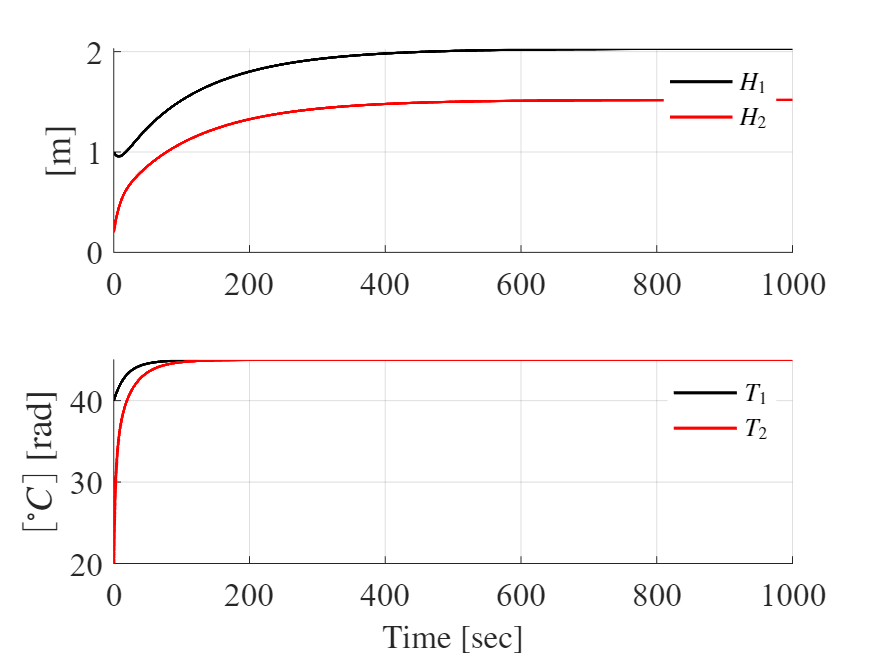

t = logsout.getElement('H1').Values.Time;
H1 = logsout.getElement('H1').Values.Data;
H2 = logsout.getElement('H2').Values.Data;
Tm1 = logsout.getElement('T1').Values.Data;
Tm2 = logsout.getElement('T2').Values.Data;

figure
h1 = subplot(2,1,1);
set(h1,'FontName','times','FontSize',16)
hold on
grid on
plot(t,H1,'k',t,H2,'r','LineWidth',1.5)
ylabel('[m]','Interpreter','latex');
leg1 = legend('$H_1$','$H_2$','Location','NorthEast');
set(leg1,'FontName','times','FontSize',12,'Interpreter','latex','box','off')

h2 = subplot(2,1,2);
set(h2,'FontName','times','FontSize',16)
hold on
grid on
plot(t,Tm1,'k',t,Tm2,'r','LineWidth',1.5)
ylabel('$[^\circ C]$ [rad]','Interpreter','latex');
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex');
leg2 = legend('$T_1$','$T_2$','Location','NorthEast');
set(leg2,'FontName','times','FontSize',12,'Interpreter','latex','box','off')

**Numerically Linearlize the system around stationary point**

u0 = [u10,u20,v10,v20,v30]';
[A,B,C,D] = linmod('MyTwoTankSystem_Linearize',x0,u0);
%[A,B,C,D] = linmod('TwoTankSystem_Linearize',x0,u0);
%[A,B,C,D] = linmod('MyTwoTankSystem',x0);
A

A =    -0.0499    0.0499         0         0
    0.0499   -0.0667         0         0
   -0.0000         0   -0.0251         0
    0.0000   -0.0000    0.0335   -0.0335


Bv = B(:,3:5)

Bv =          0         0         0
   -4.1761         0         0
         0    0.0126    0.0126
         0         0         0


B = B(:,1:2)

B =     0.0051    0.0051
         0         0
    0.0377   -0.0377
         0         0


C

C =          0    2.0000         0         0
         0         0         0    0.1000


Dv = D(:,3:5)

Dv =      0     0     0
     0     0     0


D = D(:,1:2)

D =      0     0
     0     0


## Discretization

% choose the sampling time
lambda = eig(A)

lambda =    -0.0335
   -0.0251
   -0.1090
   -0.0077


taui = 1./abs(lambda)

taui =    29.8101
   39.8193
    9.1773
  130.0944


Ts = ceil(min(taui)/10)

Ts =      1


[F,G] = c2d(A,B,Ts)

F =     0.9525    0.0471         0         0
    0.0471    0.9366         0         0
   -0.0000   -0.0000    0.9752         0
    0.0000   -0.0000    0.0326    0.9670


G =     0.0050    0.0050
    0.0001    0.0001
    0.0372   -0.0372
    0.0006   -0.0006


[~,Gv] = c2d(A,Bv,Ts)

Gv =    -0.1003         0         0
   -4.0415         0         0
    0.0000    0.0124    0.0124
    0.0000    0.0002    0.0002


## Stability assesing

% open-loop eigenvalues
lambda_OL = eig(A);
if sum(real(lambda_OL) < 0) == size(A,1)
    disp('Open loop system is asymptotically stable')
elseif sum(real(lambda_OL) < 0) < size(A,1)
    tmp = size(A,1) - sum(real(lambda_OL) < 0);
    if sum(real(lambda_OL) > 0) >= 1 || tmp > 1
        disp('Open loop system is unstable')
    elseif sum(real(lambda_OL) > 0) == 0 && tmp == 1
        disp('Open loop system is marginally stable')
    end
end

Open loop system is asymptotically stable


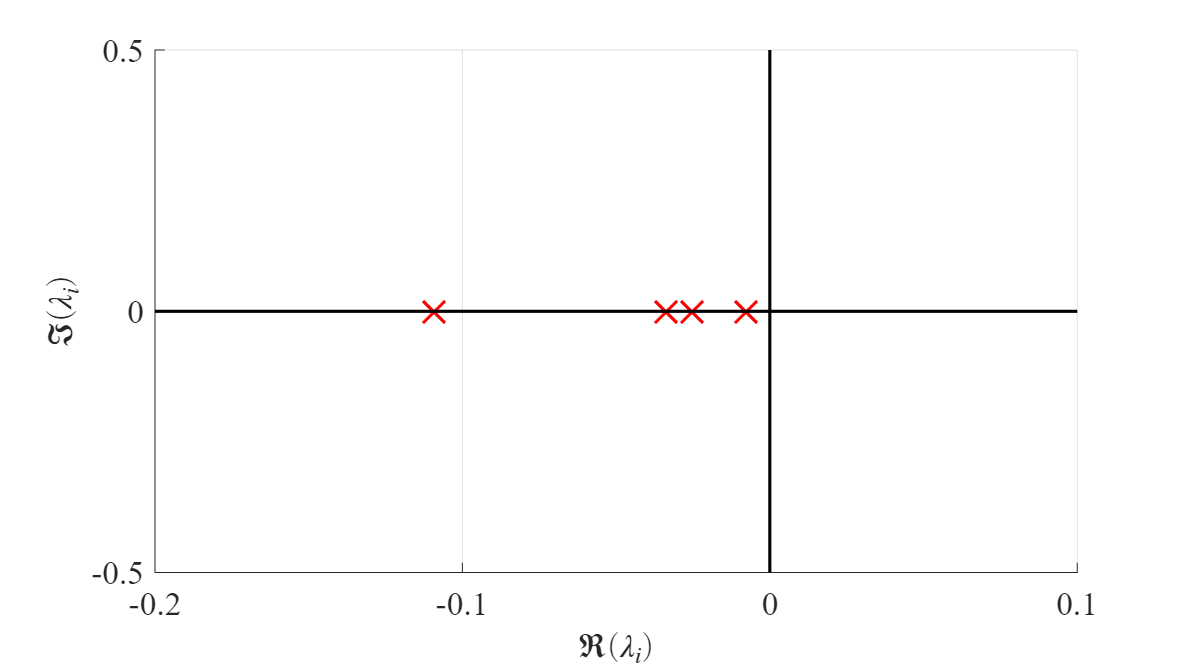


TwoTankSys = ss(A,B,C,D);
[w,z] = damp(TwoTankSys);
figure('Units','normalized','OuterPosition',[0 0 1 1],'PaperOrientation','landscape','Renderer','painter')
h1 = axes;
set(h1,'FontName','times','FontSize',16)
hold on
grid on
h1 = plot(real(lambda_OL),imag(lambda_OL),'x','MarkerSize',15,'MarkerEdgeColor','r','LineWidth',1.5);
line([floor(min(real(lambda_OL))) ceil(max(real(lambda_OL)))+0.1],[0 0],'Color','k','LineWidth',1.5)
line([0 0],[floor(min(imag(lambda_OL)))-1 ceil(max(imag(lambda_OL)))+1],'Color','k','LineWidth',1.5)
xlabel('$\Re(\lambda_i)$','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$\Im(\lambda_i)$','FontName','times','FontSize',16,'Interpreter','latex')
xlim([-0.2 0.1])
ylim([-0.5 0.5])

## Controllability & Observability

Mc = ctrb(A,B);
if rank(Mc) == size(A,1)
    disp('Open loop system is controllable')
else
    dimCs = rank(Mc);
    disp('Open loop system is not controllable and the controllability subspace has dimension ',dimCs);
end

Open loop system is controllable


% 这儿有问题，到底可控子空间的维度是rank(Mc)还是n-p
Mo = obsv(A,C);
if rank(Mo) == size(A,1)
    disp('Open loop system is observable')
else
    dimOs = rank(Mo);
    disp('Open loop system is not observable and the observability subspace has dimension ',dimOs);
end

Open loop system is observable


Example 4.13 With Multiple Integrators

eig(A)

ans =    -0.0335
   -0.0251
   -0.1090
   -0.0077
